# **Rat: 0811**

**TODO: deal with this calibration part: **

**  for i=1:length(ratMks)**

**        rat.(ratMks{i}) = rat.(ratMks{i})/4.7243; %calibrate**

**    end**

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('collate_stats.mat'); 
datert = '160811'; 
%load 0902- 4, 6, 7, 9, 10
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Recruitment curves**: (VL, SM)

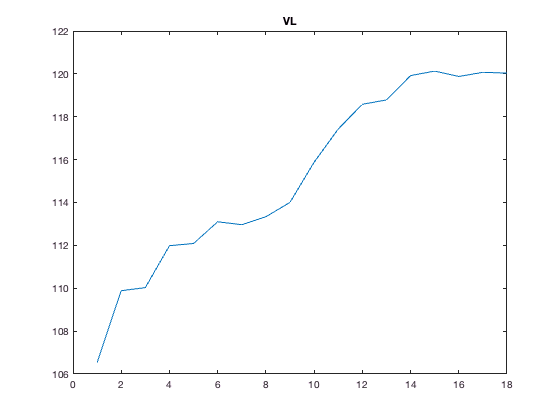

%Use figure numbers in the "100" range
%05 will be the trial for VL
%find the correct trial
trnum = 5; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0);

%Now do the recruitment curve. 
%somehow need to determine whether this is based on a single file or on many files. 
[pks, locs] = final_rc(rats{idx}.angles.knee, 0, 101, 800, 2, [], []); 
plot(1:length(locs), pks); 
title('VL')

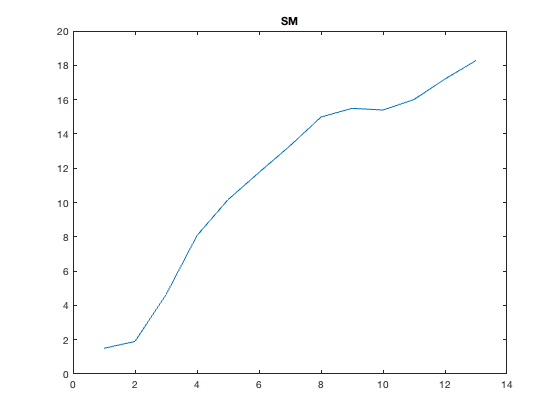


%06 will be the trial for SM
%find the correct trial
trnum = 6; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = [b{:}] == 0; 
%recruitment curve. 
rm_idx = [6:10 12 16]; 
add_idx = [[1.5 800]; [1.9 2000]]; 
[pks, locs] = final_rc(rats{idx}.angles.knee, 1, 102, 700, 1, rm_idx, add_idx); 
plot(1:length(locs), pks); 
title('SM')

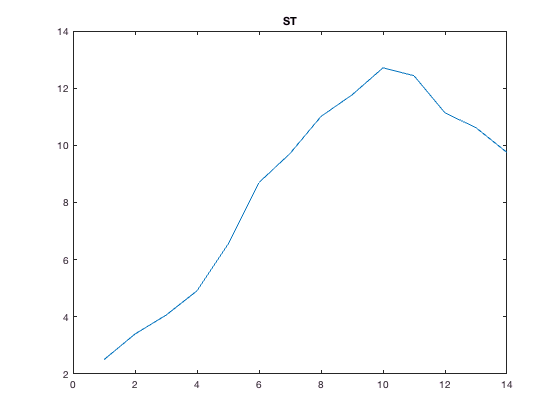


%08 will be the trial for ST
%find the correct trial
trnum = 8; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = [b{:}] == 0; 
%recruitment curve. 
[pks, locs] = final_rc(rats{idx}.angles.knee, 1, 102, 700, .6, [], []); 
plot(1:length(locs), pks); 
title('ST')

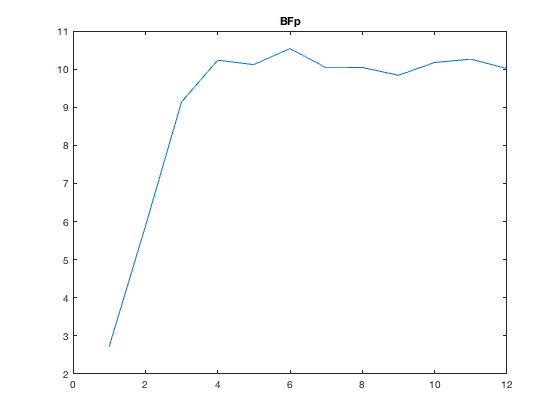


%09 will be the trial for BFp
%find the correct trial
trnum = 9; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = [b{:}] == 0; 
%recruitment curve. 
[pks, locs] = final_rc(rats{idx}.angles.knee, 1, 102, 700, .6, [], []); 
plot(1:length(locs), pks); 
title('BFp')

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

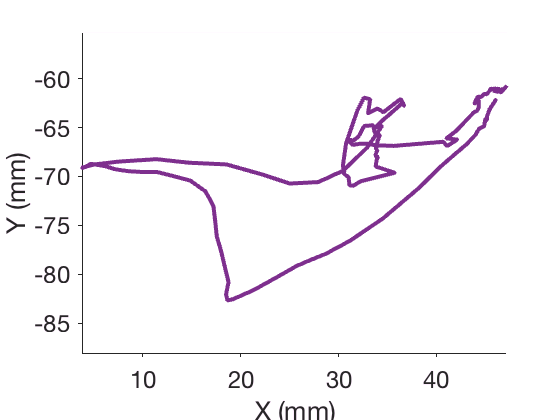

%10 will be a "normal" trial
trnum = 10; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = [9 10]; 
%ja_time(temprat, swing_time_idx{20}, 101)
%ja_avg(temprat, swing_time_idx{stat_idx}, 102, elim_steps)
%ja_trace(temprat, swing_time_idx{stat_idx}, 103, elim_steps)

%trajectories: by default, these track the endpoint
%traj_trace(temprat, swing_time_idx{stat_idx}, 104, elim_steps)
traj_avg(temprat, swing_time_idx{stat_idx}, 105, elim_steps)

**Change in height, length**

10 has less cocontraction than 18-20

18 - freq 40, slowdown 4

19 - freq 40, slowdown 3

20 - freq 60, slowdown 4, adjust amplitude (lower amp IP, GS, ST)

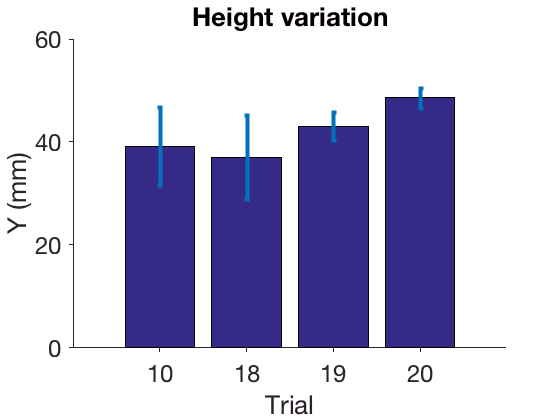

%get the rats you're using, get the sets of swing_times you're using, and elim_steps
%using those sets, get the values of the maximum difference between low point and high 
%point of each step. 

%take all the relevant trials and review them
trnums = [10 18:20]; 
clear('idx'); 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
end

lbls = {}; 
clear('h', 'l', 'lbls'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.aug11.h = h; 
heights.aug11.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

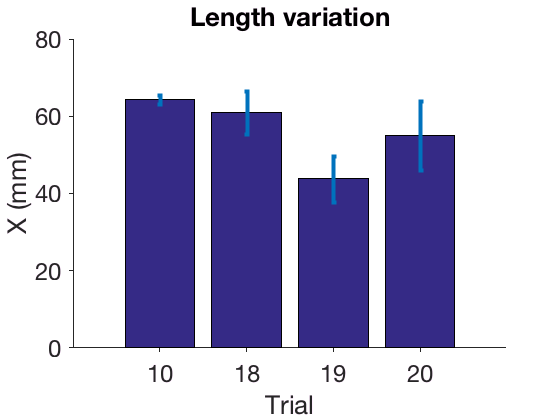


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:4, mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

# Rat 0902 (no RC)

**Load data**

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('collate_stats.mat'); 
datert = '160902'; 
%load 0902- 4, 6, 7, 9, 10
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

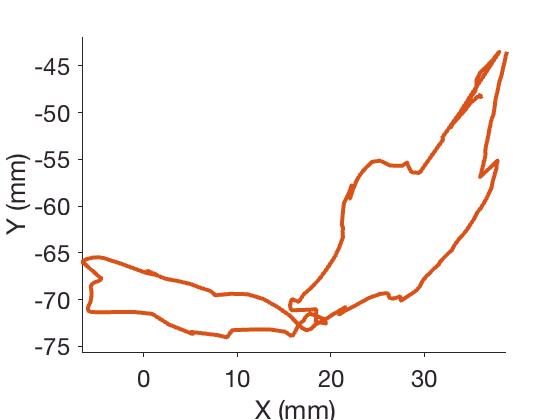

%4 will be a "normal" trial
trnum = 4; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = [9 10]; 
traj_avg(temprat, swing_time_idx{stat_idx}, 207, elim_steps)

**Change in height, length**

6 - standard (but no VL activation, as for all on this day)

7 - inc ip/st x 1.2

9 - inc ip/st x 2

10 - standard again

So the step gets shorter with the same things that make it higher

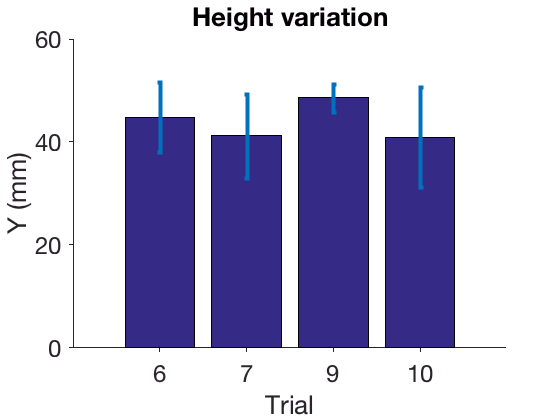

%get the rats you're using, get the sets of swing_times you're using, and elim_steps
%using those sets, get the values of the maximum difference between low point and high 
%point of each step. 

%take all the relevant trials and review them
trnums = [6 7 9 10]; 
clear('idx'); 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
end

lbls = {}; 
clear('h', 'l', 'lbls'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.sep02.h = h; 
heights.sep02.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

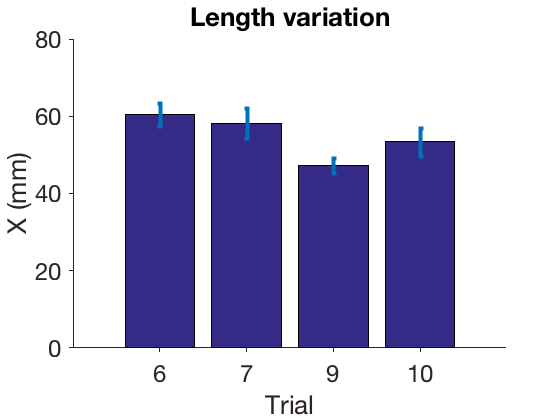


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:length(trnums), mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

# Rat 0908 (no RC)

**Load data**

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('collate_stats.mat'); 
datert = '160908'; 
%load 0902- 4, 6, 7, 9, 10
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

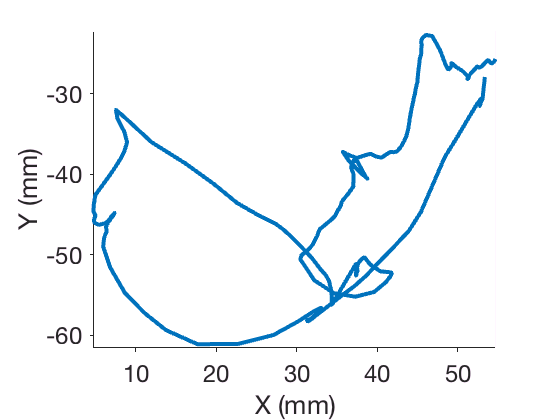

%4 will be a "normal" trial
trnum = 1; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = []; 
traj_avg(temprat, swing_time_idx{stat_idx}, 208, elim_steps)

**Change in height, length**

1:3, 8, 9

1 and 2 are same which is weird. 3 is minus VL but same stim otherwise

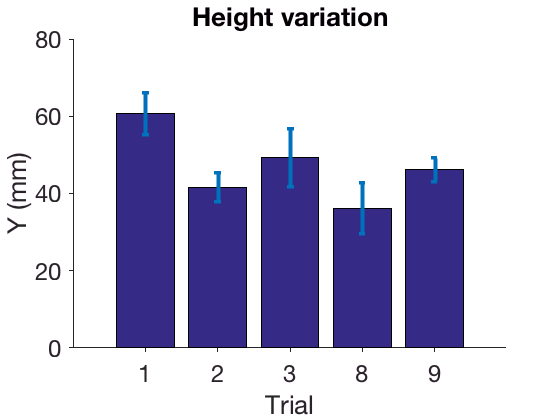

%get the rats you're using, get the sets of swing_times you're using, and elim_steps
%using those sets, get the values of the maximum difference between low point and high 
%point of each step. 

%take all the relevant trials and review them
trnums = [1:3 8 9]; 
clear('idx'); 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
end

lbls = {}; 
clear('h', 'l', 'lbls'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.sep08.h = h; 
heights.sep08.l = l; 
heights.sep08.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

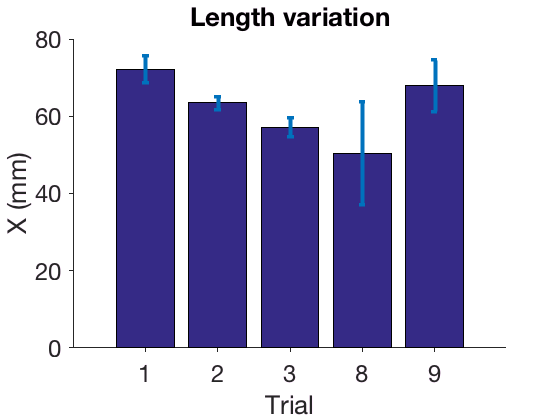


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:length(trnums), mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

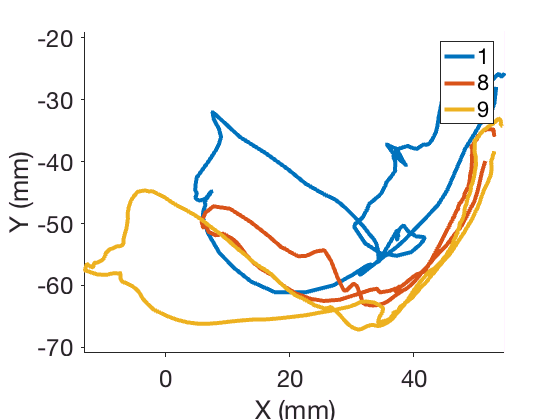


clear('idx'); 
leg210 = {}; 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
    elim_steps = [10]; 
    if find(trnums(t)==[1 8 9])
        figure(211); hold on; 
        leg210{end+1} = int2str(trnums(t)); 
        traj_avg(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, 211, elim_steps)
    end
end
figure(211); legend(leg210); 

# Rat 1006 (no RC)

**Load data**

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('161006_stats.mat'); 
datert = '161006'; 
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

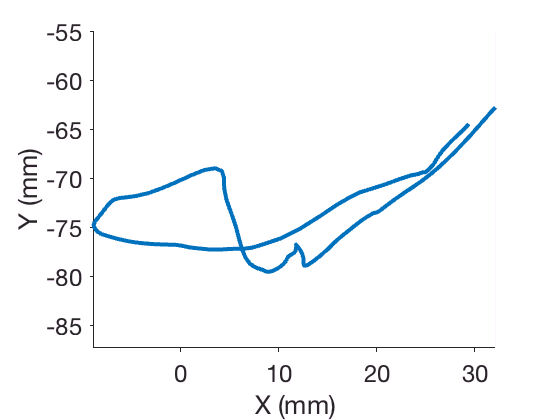

% "normal" trial
trnum = 8; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = []; 
traj_avg(temprat, swing_time_idx{stat_idx}, 209, elim_steps)

**Change in height, length**

1:14 are messing with length of time in stance phase and speed of the step

15:26 are height and length. 20 failed to reconstruct properly.

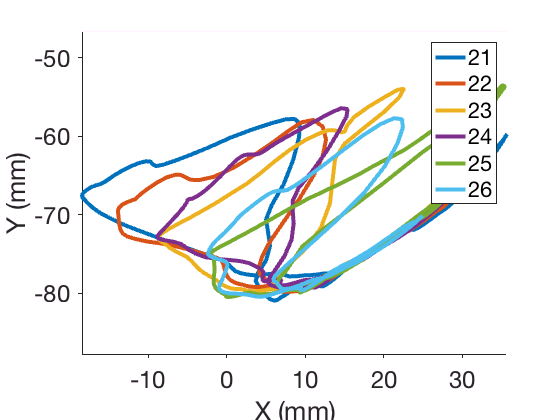

%get the rats you're using, get the sets of swing_times you're using, and elim_steps
%using those sets, get the values of the maximum difference between low point and high 
%point of each step. 

%take all the relevant trials and review them
trnums = [6:8 11 15:19 21:26]; 
clear('idx'); 
leg210 = {}; 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
    elim_steps = [10]; 
    if find(trnums(t)==21:26)
        figure(215); hold on; 
        leg210{end+1} = int2str(trnums(t)); 
        traj_avg(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, 215, elim_steps)
    end
end
figure(215); 
legend(leg210); 

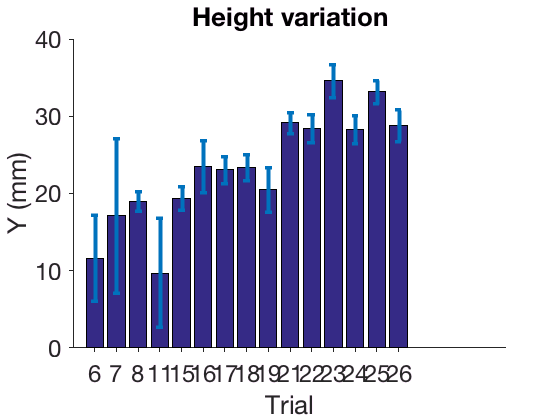


lbls = {}; 
clear('h', 'l'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.oct06.h = h; 
heights.oct06.l = l; 
heights.oct06.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

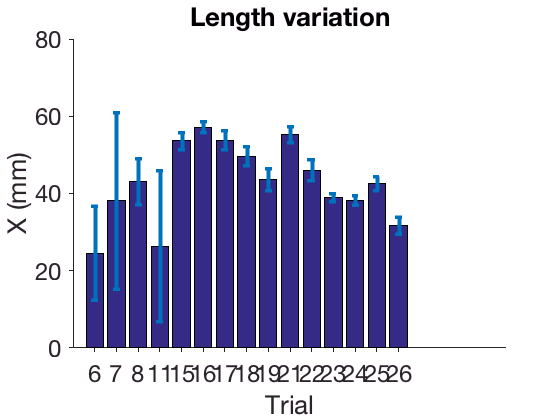


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:length(trnums), mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

# Rat 1101 (no RC)

**Load data**

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('collate_stats.mat'); 
datert = '161101'; 
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

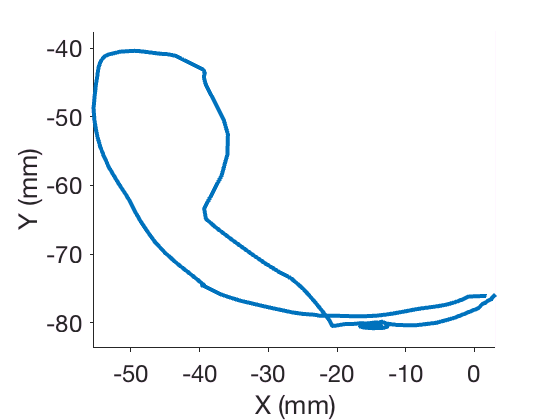

% "normal" trial
trnum = 2; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = []; 
traj_avg(temprat, swing_time_idx{stat_idx}, 210, elim_steps)

**Change in height, length**

Mostly messing with height here, and at some point the electrode placement changed

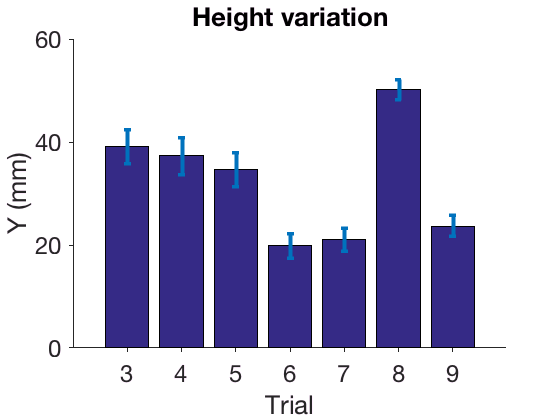

%take all the relevant trials and review them
trnums = [3:9]; 
clear('idx'); 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
end

lbls = {}; 
clear('l', 'h'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.nov01.h = h; 
heights.nov01.l = l; 
heights.nov01.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

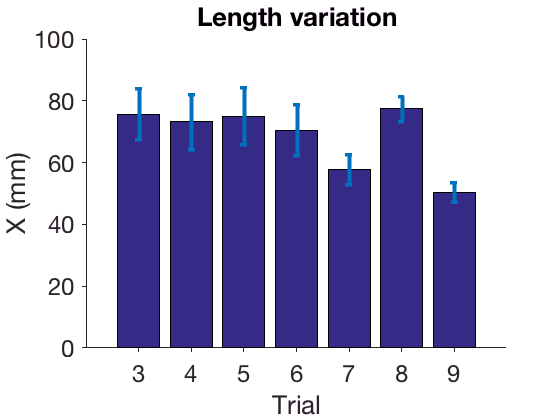


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:length(trnums), mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

# Rat 1116

cd('/Users/mariajantz/Documents/Work/data/kinematics/processed/'); 
load('collate_stats.mat'); 
datert = '161116'; 
a = dir([datert '*']); 
rats = cell(size(a, 1), 1); 
for i=1:size(a, 1)
    load(a(i).name); %will overwrite previous set of data so append to array
    %assign "rat" struct to an array
    rat.trial = a(i).name; 
    rats{i} = rat; 
end

**Recruitment curves**: (VL, SM)

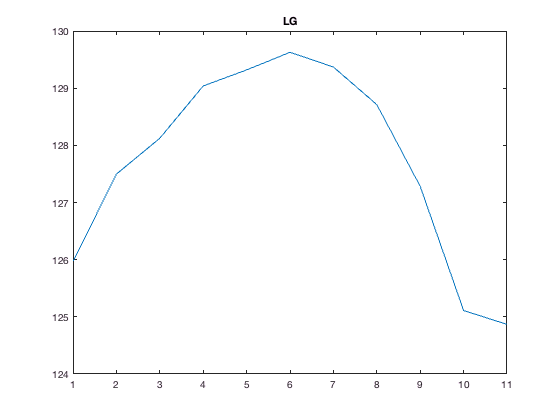

%Use figure numbers in the "100" range
%05 will be the trial for LG
%find the correct trial
trnum = 1; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0);

%Now do the recruitment curve. 
%somehow need to determine whether this is based on a single file or on many files. 
[pks, locs] = final_rc(rats{idx}.angles.ankle, 0, 111, 175, 2, [], []); 
plot(1:length(locs), pks); 
title('LG')

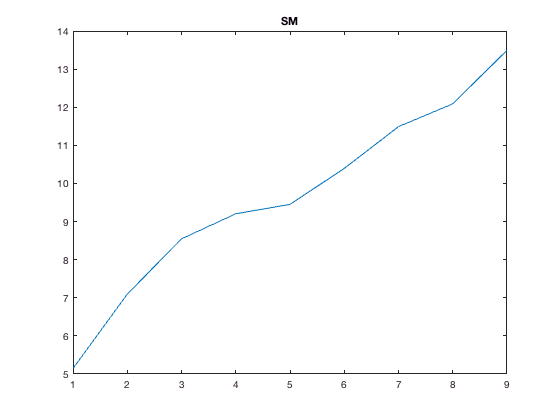


%06 will be the trial for SM
%find the correct trial
trnum = 2; 
%get location of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = [b{:}] == 0; 
%recruitment curve. 
%rm_idx = [6:10 12 16]; 
%add_idx = [[1.5 800]; [1.9 2000]]; 
[pks, locs] = final_rc(rats{idx}.angles.knee, 1, 112, 175, 1, [], []); 
plot(1:length(locs), pks); 
title('SM')

**Normal range of motion** (with speed, step shape avg, step shape variation, hip/knee/ankle extremes)

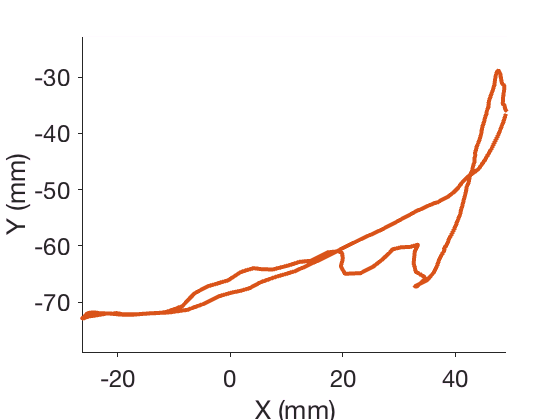

%"normal" trial
trnum = 3; 
%get index of trial (important in case of skipped trials)
b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnum, '%02d')])), rats, 'UniformOutput', false); 
idx = find([b{:}] == 0); 

temprat = rats{idx}; % this is the rat we're using
%also, I need to find the split_steps info from whichever file I saved it in (check collate)
c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnum, '%02d')])), trialname, 'UniformOutput', false);
stat_idx = find([c{:}] == 0); 
elim_steps = [8 9 10]; 
%ja_time(temprat, swing_time_idx{20}, 101)
%ja_avg(temprat, swing_time_idx{stat_idx}, 102, elim_steps)
%ja_trace(temprat, swing_time_idx{stat_idx}, 103, elim_steps)

%trajectories: by default, these track the endpoint
%traj_trace(temprat, swing_time_idx{stat_idx}, 104, elim_steps)
traj_avg(temprat, swing_time_idx{stat_idx}, 115, elim_steps)

**Change in height, length**

4:8 are messing with height

9:11 are messing with length

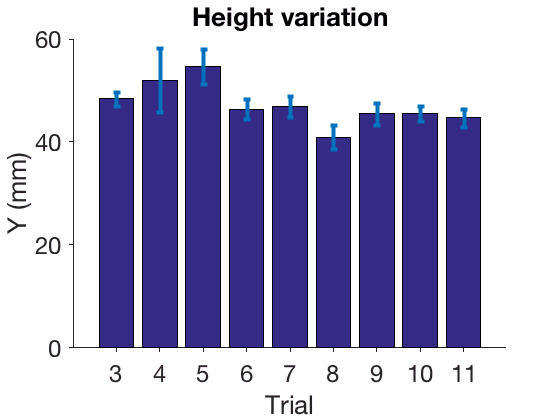

%get the rats you're using, get the sets of swing_times you're using, and elim_steps
%using those sets, get the values of the maximum difference between low point and high 
%point of each step. 

%take all the relevant trials and review them
trnums = [3:11]; 
clear('idx'); 
for t = 1:length(trnums)
    b = cellfun(@(x) isempty(strfind(x.trial, [datert '_' num2str(trnums(t), '%02d')])), rats, 'UniformOutput', false);
    c = cellfun(@(x) isempty(strfind(x, [datert '_' num2str(trnums(t), '%02d')])), trialname, 'UniformOutput', false);
    %define first variable in each pair as the index in the rats cell array, and
    %the second as the index of the swing_time 
    idx(t, :) = [find([b{:}] == 0) find([c{:}] == 0)]; 
end

lbls = {}; 
clear('l', 'h'); 
for t = 1:length(trnums)
    h{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 2);
    l{t} = step_range(rats{idx(t, 1)}, swing_time_idx{idx(t, 2)}, elim_steps, 1);
    lbls{t} = int2str(trnums(t)); 
end
heights.nov16.h = h; 
heights.nov16.l = l; 
heights.nov16.trnum = trnums; 

figure(); hold on; 
mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
bar(mean_h)
errorbar(1:length(trnums), mean_h, std_h, '.', 'linewidth', 4)

ax = gca; 
ylabel('Y (mm)');
xlabel('Trial');
title('Height variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

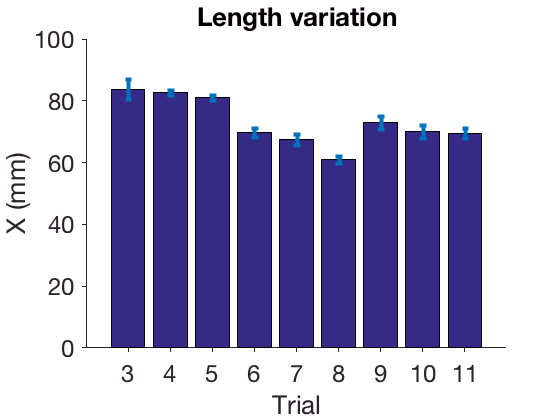


figure(); hold on; 
mean_l = cell2mat(cellfun(@(x) mean(x), l, 'UniformOutput', false));
std_l = cell2mat(cellfun(@(x) std(x), l, 'UniformOutput', false));
bar(mean_l)
errorbar(1:length(trnums), mean_l, std_l, '.', 'linewidth', 4)

ax = gca; 
ylabel('X (mm)');
xlabel('Trial');
title('Length variation'); 
%lbls = cellfun(@(x) x.trial, trialname(idx(:, 2)), 'UniformOutput', 0)
set(ax, 'XTick', [1:length(trnums)]);
set(ax, 'XTickLabel', lbls); 
set(ax, 'fontsize', 24);
set(gca,'TickDir','out')

# Now look at heights overall - averages.

have built up a struct called heights

fieldnames = {'sep08', 'oct06', 'nov16'}; 
tr = {[1, 8, 9], [8, 22, 23], [3, 4, 5]}; 

% [vals, idx] = intersect(heights.(fieldnames{1}).trnum, tr{1}); 
% h = heights.(fieldnames{1}).h(idx)
% 
% figure(); hold on; 
% mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));
% std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
% bar(mean_h)
% errorbar(1:length(idx), mean_h, std_h, '.', 'linewidth', 4)

for f=1:length(fieldnames)
    %let the normal step (100%) always be the first number in the set
    [vals, idx] = intersect(heights.(fieldnames{1}).trnum, tr{1}); 
    h = heights.(fieldnames{f}).h(idx); 
    mean_h = cell2mat(cellfun(@(x) mean(x), h, 'UniformOutput', false));    
    std_h = cell2mat(cellfun(@(x) std(x), h, 'UniformOutput', false));
    
    %divide by normal step to get percentages
    for m=1:length(mean_h)
        norm_mean = mean_h(m)/mean_h(1)
        norm_std = std_h(m)/std_h(1)

    end
end

norm_mean = 1

norm_std = 1

norm_mean = 0.5969

norm_std = 1.2061

norm_mean = 0.7622

norm_std = 0.5607

norm_mean = 1

norm_std = 1

norm_mean = 0.8397

norm_std = 1.2688

norm_mean = 1.6743

norm_std = 0.2697

norm_mean = 1

norm_std = 1

norm_mean = 0.9583

norm_std = 1.4873

norm_mean = 0.9679

norm_std = 1.4972